# **InverseJacobiSD**

[Inverse of the Jacobi elliptic function sd](https://dlmf.nist.gov/22.15)

## Definition


$${\textrm{sd}}^{-1} \left(x\left|m\right.\right)\equiv \left\lbrace \begin{array}{cc}
\mathit{\mathbf{F}}\left(\frac{x}{\sqrt{1+mx^2 }}\left|m\right.\right) & m\le 1\\
\frac{{\textrm{sd}}^{-1} \left(x\sqrt{m}\left|m^{-1} \right.\right)}{\sqrt{m}} & m>1
\end{array}\right.$$



$${\mathrm{sd}}^{-1} \left(x,k\right)\equiv {\mathrm{sd}}^{-1} \left(x\left|k^2 \right.\right)$$


where *m *is the parmeter, *k *is the modulus, $\mathit{\mathbf{F}}\left(x\left|m\right.\right)$ is  Jacobi form of the elliptic integral of the first kind.

Domain:   If $-\infty <m\le 1$ then $\left|x\right|<1/\sqrt{m-1}$ . If $m>1$ then $-\infty \le x\le \infty$.For the specified domain, the  codomain  is the set of real numbers.

Basic features:

${\mathrm{sd}}^{-1} \left(-x\left|m\right.\right)=-{\mathrm{sd}}^{-1} \left(x\left|m\right.\right)$   (odd)

Special values:

   
$${\mathrm{sd}}^{-1} \left(0\left|m\right.\right)=0$$


${\mathrm{sd}}^{-1} \left(x\left|0\right.\right)={\mathrm{sin}}^{-1} x$,    ${\mathrm{sd}}^{-1} \left(x\left|1\right.\right)=\sinh^{-1} x$

Identities:


$${\mathrm{sd}}^{-1} \left(\mathrm{sd}\left(x\left|m\right.\right)\left|m\right.\right)=x,\;\;\;\;\left|x\right|<K\left(m\right)$$



$$\textrm{sd}\left({\textrm{sd}}^{-1} \left(x\left|m\right.\right)\left|m\right.\right)=x$$


$K\left(m\right)$ is the complete elliptic integral of the first kind .

## Syntax

Y = InverseJacobiSD(X,K)

y = ijsd(x,k)

Y = mInverseJacobiSD(X,M)

y = mijsd(x,m)

## Desdription

**Y = InverseJacobiSD(X,K)** return${\;\mathrm{sd}}^{-1} \left(x,k\right)$ for each element of the arrays X and K (modulus). X and K must be real and the ssde size or any of them can be sdalar. **InverseJacobiSD** is the wrapper function which calls the functions **ijsd** element-wise via the function **ufun2**.

**y = ijsd(x,k)** return the value of ${\mathrm{sd}}^{-1} \left(x,k\right)$ for argument *x* and the modulus k. It is assumed that the input arguments are real sdalars without check. y is NaN if any of   the input arguments is invalid or convergence failed. **ijsd** is the wrapper function which calls the functions **mijsd**.

**Y = mInverseJacobiSD(X,M)** returns ${\mathrm{sd}}^{-1} \left(x\left|m\right.\right)$ for each element of the arrays X and M (parsdeter). X and M must be real and the ssde size or any of them can be sdalar. **mInverseJacobiSD** is the wrapper function which calls the functions **mijsd** element-wise via the function **ufun2**.

**y = mijsd(x,m)** compute value of ${\mathrm{sd}}^{-1} \left(x\left|m\right.\right)$ for  argument x and the parsdeter m. It is assumed that the input arguments are real sdalars without check. y is NaN if any of  the input arguments is invalid or convergence failed.  **mijsd **call the function **melF **for calculation of ${\mathrm{sd}}^{-1} \left(x\left|m\right.\right)$ ([1-2]).

## Precision

## **Numerical Examples**

**Scalar input**

format long
k = 0.5;
x = 0.5;
[ijsd(x,k), InverseJacobiSD(x,k), mijsd(x,k^2), mInverseJacobiSD(x,k^2)]

ans =    0.511729310325697   0.511729310325697   0.511729310325697   0.511729310325697


% Maple 2.85977139929949528


Accuracy.

fprintf('%.16g\n',mijsd(0.5,-4)) 

NaN


%  Maple  0.4159330998068017_33

Special values

m=0.5;
disp(mijsd(0,m))  % m < 1 !!!

     0



disp(mijsd(1,m)-melF(1/sqrt(2),m))

   0.202038924802882



x=0.5;
disp(mijsd(x,0) - asin(x)) 

     0



disp(mijsd(x,1) - asinh(x))

     0



Identities

m = -2;
x = 0.5; % |x| <= 1
disp(mJacobiSD(mInverseJacobiSD(x,m),m)-x)

    -5.551115123125783e-17




k = 0.99995;
x = 0.9999*elK(k);
disp(InverseJacobiSD(JacobiSD(x,k),k)-x)

     3.389999392311438e-11



m = 2; % m>1
x = 0.2; % x < sqrt(m-1)
disp(mijsd(x,m)-mijsc(x*sqrt(m),1/m)/sqrt(m))

     0



m = 0.5;
x = 0.2;
disp(mijsd(-x,m)+mijsd(x,m))

     0



**Vector input**

m = [0.1, 0.5, 0.89, 0.99995];
x = 0.2*ones(size(m));
disp(mJacobiSD(mInverseJacobiSD(x,m),m)-x)

   1.0e-16 *

  -0.555111512312578   0.277555756156289   0.277555756156289                   0



**Matrix input**

m = [0.1, 0.5, 0.89; -1, -97, 0.99995 ]';
x = 0.2*ones(size(m));
disp(mJacobiSD(mInverseJacobiSD(x,m),m)-x)

   1.0e-16 *

  -0.555111512312578   0.555111512312578
   0.277555756156289                 NaN
   0.277555756156289                   0



## **Plot **

**Example 1**

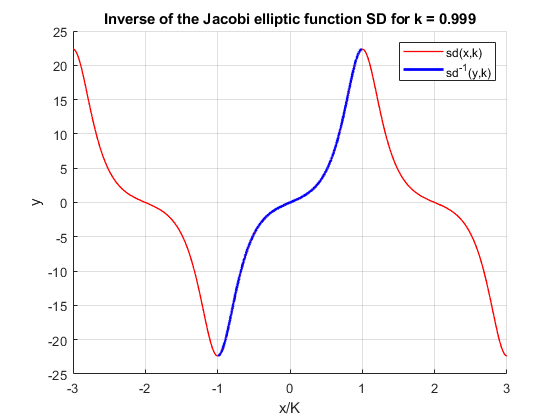

figure
hold on
x=-3:0.01:3;
k = 0.999;
M = elK(k);
plot(x,JacobiSD(M*x,k),'LineWidth',1.0,'Color','red')
x=-102:0.01:102;
plot(InverseJacobiSD(x,k)/M,x,'LineWidth',2,'Color','blue')
legend('sd(x,k)','sd^{-1}(y,k)') %,'Position','best')
xlabel('x/K')
ylabel('y')
%xlim([-1.1 1.1])
%ylim([-5 5])
title(sprintf('Inverse of the Jacobi elliptic function SD for k = %g',k))
grid on
hold off

**Example 2**

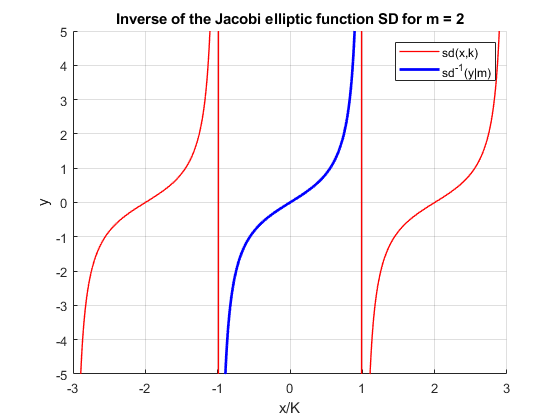

figure
hold on
x=-3:0.01:3;
m = 2;
if m < 1
    M = melK(m);
    xlabel('x/K')
elseif m > 1
    M = melK(1/m)/sqrt(m);
    xlabel('x/K')
else
    M = 1;
    xlabel('x')
end
plot(x,mJacobiSD(M*x,m),'LineWidth',1.0,'Color','red')
x=-102:0.01:102;
plot(mInverseJacobiSD(x,m)/M,x,'LineWidth',2,'Color','blue')
legend('sd(x,k)','sd^{-1}(y|m)') %,'Position','best')
ylabel('y')
%xlim([-1.1 1.1])
ylim([-5 5])
title(sprintf('Inverse of the Jacobi elliptic function SD for m = %g',m))
grid on
hold off

**Example 3**

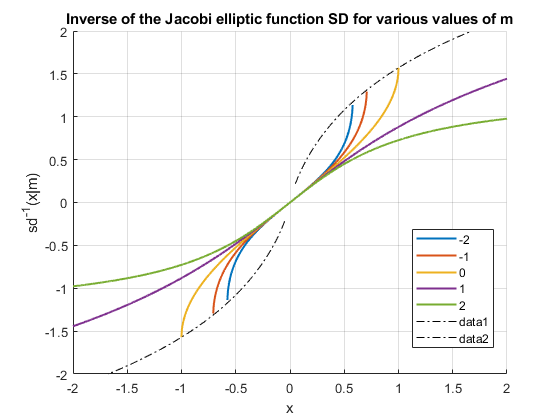

figure
hold on
X = -2:0.001:2;
M = [-2,-1,0,1,2];
SN = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mInverseJacobiSD(X,M(i));
end
plot(X,SN,'LineWidth',1.5)
axis([min(X) max(X) -2 2])
grid on
legend(clg{1:length(M)},'Location','Best')
title('Inverse of the Jacobi elliptic function SD for various values of m')
N=-400:0.01:1;
X = 1./sqrt(1-N);
plot(X,mInverseJacobiSD(X,N),'k-.')
plot(-X,-mInverseJacobiSD(X,N),'k-.')
xlabel('x')
ylabel('sd^{-1}(x|m)')

**Example 4**

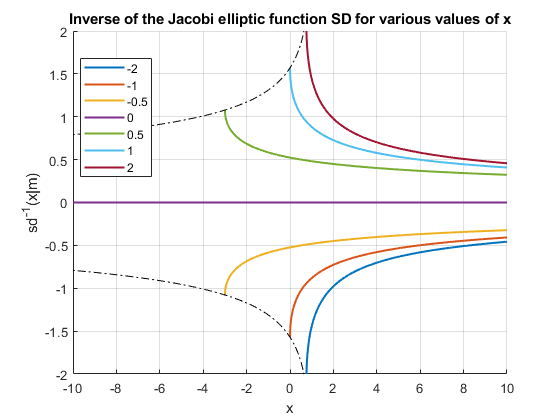

figure
hold on
M = -10:0.01:10;
X = [-2,-1,-0.5,0,0.5,1,2];
SN = zeros(length(X),length(M));
clg{length(X)}=[];
for i = 1:length(X)
     clg{i} = num2str(X(i));
    SN(i,:) = mInverseJacobiSD(X(i),M);
end
plot(M,SN,'LineWidth',1.5)
axis([min(M) max(M) -3 3])
ylim([-2  2])
grid on
legend(clg{1:length(X)},'Location','Best')
title('Inverse of the Jacobi elliptic function SD for various values of x')
xlabel('x')
ylabel('sd^{-1}(x|m)')
M = -200:0.01:1;
F = mInverseJacobiSD(1./sqrt(1-M),M);
plot(M,F,'k-.')
plot(M,-F,'k-.')
hold off

**Example 5**

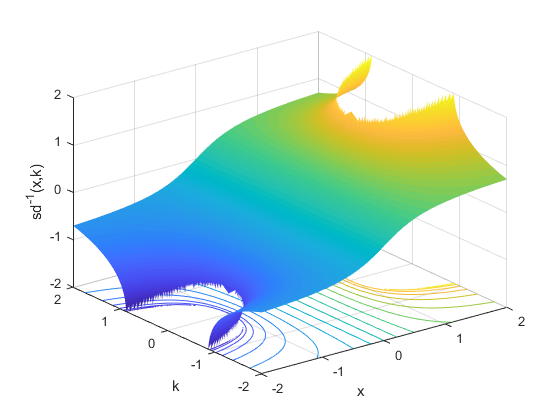

figure
x=-2:0.01:2;
k=-2:0.01:2;
zz = 2;
[X,M]=meshgrid(x,k);
hs=surfc(X,M,InverseJacobiSD(X,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -zz;
hc.LineWidth = 0.5;
hc.LevelList = -zz:zz/10:zz;
view(3)
caxis([-zz zz])
xlabel('x')
ylabel('k')
zlabel('sd^{-1}(x,k)')
zlim([-zz zz])
grid on

**Example 6**

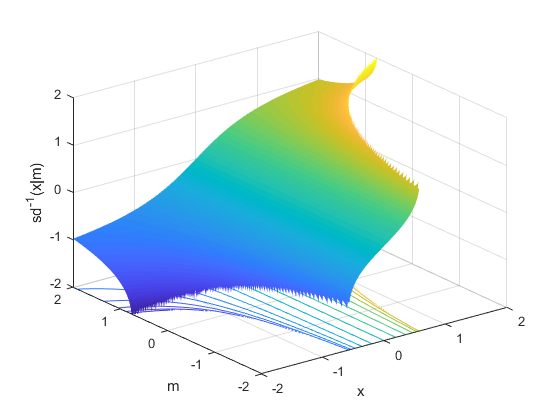

figure
x=-2:0.01:2;
m=-2:0.01:2;
zz = 2;
[X,M]=meshgrid(x,m);
hs=surfc(X,M,mInverseJacobiSD(X,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -zz;
hc.LineWidth = 0.5;
hc.LevelList = -zz:zz/10:zz;
view(3)
caxis([-zz zz])
xlabel('x')
ylabel('m')
zlabel('sd^{-1}(x|m)')
zlim([-zz zz])
grid on

**Example 7**

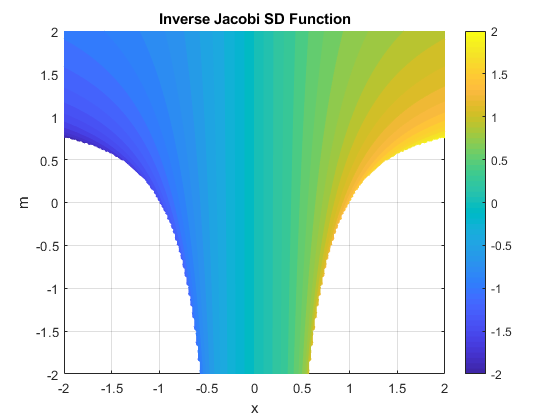

figure
f = @(x,m)mInverseJacobiSD(x,m);
fcontour(f,[-2 2 -2 2],'Fill','on','LevelList',-2:0.1:2,'MeshDensity',200)
title('Inverse Jacobi SD Function')
colorbar
xlabel('x')
ylabel('m')
grid on

**Example 8**

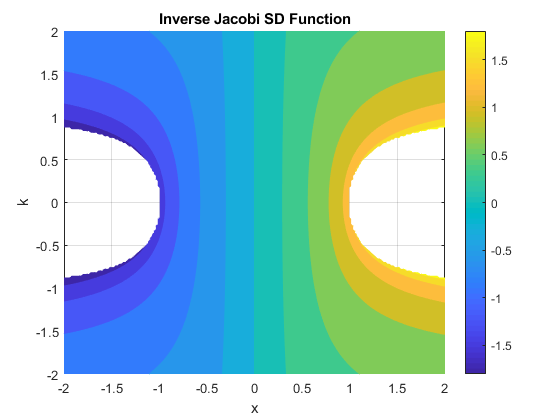

figure
f = @(x,k)InverseJacobiSD(x,k);
fcontour(f,[-2 2 -2 2],'Fill','on','LevelList',-3:0.3:3,'MeshDensity',200)
title('Inverse Jacobi SD Function')
colorbar
xlabel('x')
ylabel('k')
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Jacobian Elliptic Functions, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/22)

[Jacobi elliptic functions, Wikipedia](https://en.wikipedia.org/wiki/Jacobi_elliptic_functions)

## **References**

## See Also